% sistema massa-molla-smorzatore

% parametri
m = 1; c = 0.5; k = 2; % m=massa, c=coef. di attrito, k=cost. elastica

A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = 0;

sys = ss(A, B, C, D);
sys_tf = tf(sys); %fdt

display(sys);


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2    -2  -0.5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


display(sys_tf);


sys_tf =
 
         1
  ---------------
  s^2 + 0.5 s + 2
 
Continuous-time transfer function.



s = tf('s');
R = 0.5 * (s + 1) / (s + 2); % zero negativo

L = R * sys_tf;
display(L);


L =
 
        0.5 s + 0.5
  -----------------------
  s^3 + 2.5 s^2 + 3 s + 4
 
Continuous-time transfer function.


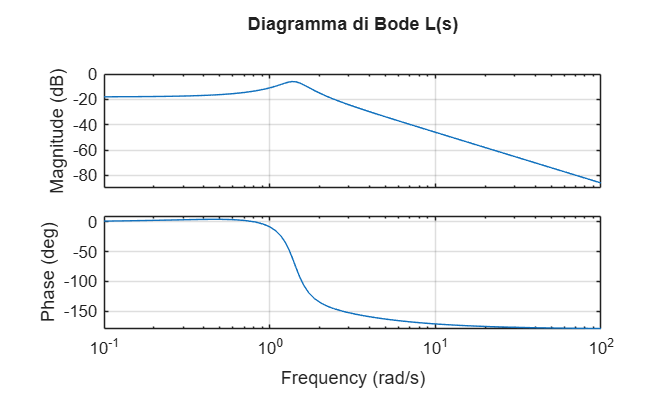


figure;
bode(L);
title("Diagramma di Bode L(s)");
grid on;

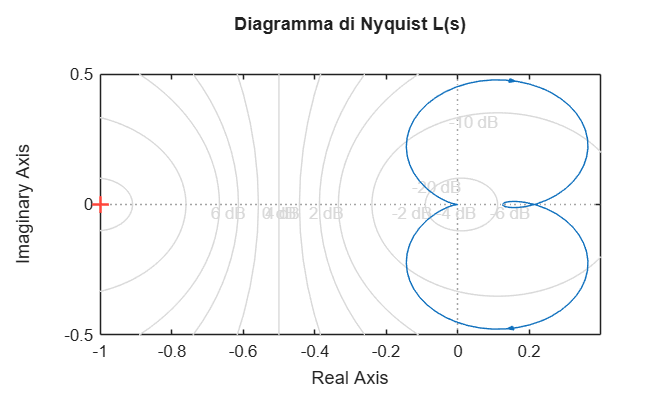


figure;
nyquist(L);
title("Diagramma di Nyquist L(s)");
grid on;

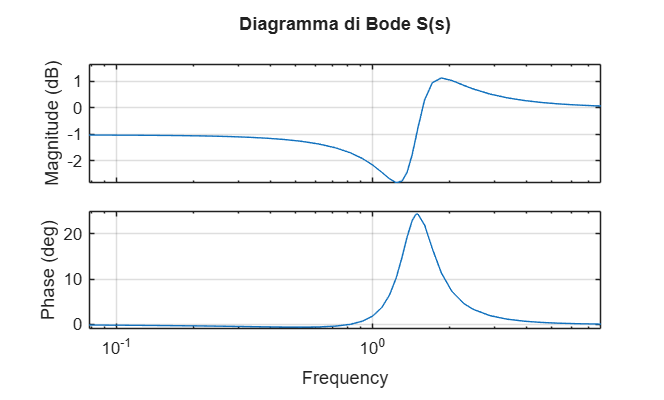


S = 1 / (1 + L);

figure;
bode(S);
title("Diagramma di Bode S(s)");
grid on;